Alen Mehmedbegovic - 301476021

Feburary 4th, 2024

Question 1

% Added three more sets of images, each with at least 4 images.

Question 2

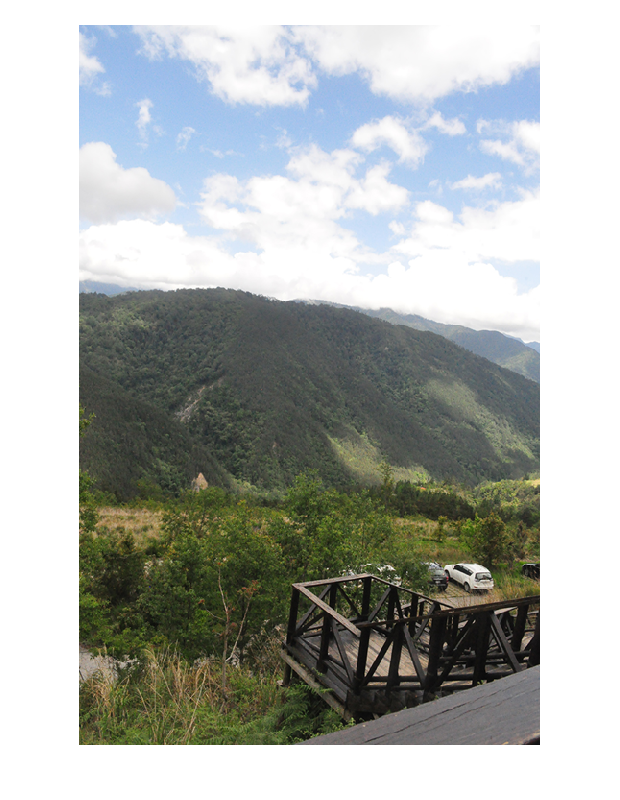

Image1 = imread("S1-im1.png");
imshow(Image1)

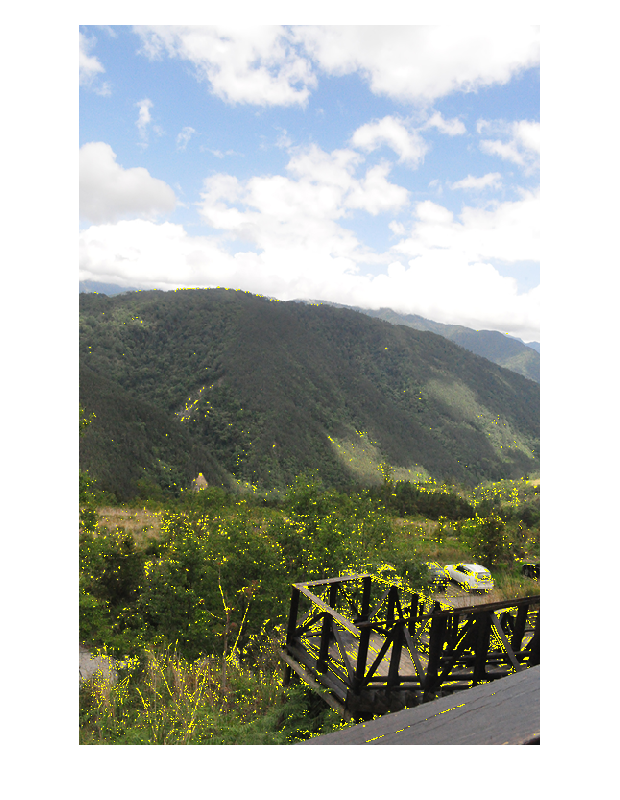

Image2 = imread("S2-im1.JPEG");
detectedcorners1 = my_fast_detector(Image1, 33);
Image1detectedcorners = imoverlay(Image1, detectedcorners1);
imshow(Image1detectedcorners);

Question 3

Question 4

Question 5 (Bonus) 

Question 2 function(s) defintion 

function detectedcorners = my_fast_detector(image, threshold)
% Following openCV website implementation "Feature Detection using FAST"

image = rgb2gray(image); % Convert to "intensity map"
[rows, cols] = size(image);
detectedcorners = zeros(rows, cols);    % Image sized logical matrix of all zeroes 
circlecornersbelow = zeros(1,16); % Used for identifying pixels below intensities range 
circlecornersabove = zeros(1,16); % Used for identifying pixels above intensities range 
highspeedtestcounterlow = 0;
highspeedtestcounterhigh = 0;

% Since our FAST detector will examine a circle of radius 3, we can't 
    % examine pixels which would have the circle go beyond the image borders.
    for i = 4:rows-3
        for j = 4:cols-3
        Ip = image(i,j); % Step 1 
        thresholdrange = [Ip - threshold, Ip + threshold]; % Step 2 
        brecircle = bresenhamcirclerad3(i,j); % Step 3 
       
        % Step 4 
            for k = 1:2:31
                % if the intensity of circle pixel is not in the threshold
                if (~(image(brecircle(k), brecircle(k + 1)) > thresholdrange(1)) && (image(brecircle(k), brecircle(k + 1)) < thresholdrange(2)))  
                    % If it's below the range
                    if(image(brecircle(k), brecircle(k + 1)) < thresholdrange(1))
                        circlecornersbelow(ceil(k/2)) = 1;
                    else
                    % If it's above
                        circlecornersabove(ceil(k/2)) = 1;
                    end
                end
            end
        % Now that we've classified our threshold points in the corners
        % matrices, we have to check for contiguous values 
            if(contiguousarc(circlecornersabove) || contiguousarc(circlecornersbelow))
                detectedcorners(i,j) = 1;
                % Step 5: high-speed test
                pixel1 = [brecircle(1), brecircle(2)];
                pixel5 = [brecircle(9), brecircle(10)];
                pixel9 = [brecircle(17), brecircle(18)];
                pixel13 = [brecircle(25), brecircle(26)];
                % According to openCV implementation, first test 1 & 9
                if(image(pixel1(1), pixel1(2)) < thresholdrange(1)) % Check if pixel 1 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                end
                if(image(pixel1(1), pixel1(2)) > thresholdrange(2)) % Check if pixel 1 is lighter than threshold
                    highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                end
                if(image(pixel9(1), pixel9(2)) < thresholdrange(1)) % Check if pixel 9 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                end
                if(image(pixel9(1), pixel9(2)) > thresholdrange(2)) % Check if pixel 9 is lighter than threshold
                    highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                end
                % Now test pixel 5 and 13
                if((highspeedtestcounterlow > 0) || (highspeedtestcounterhigh > 0)) % If we have at least 1 or 9 be yes
                    if(image(pixel5(1), pixel5(2)) < thresholdrange(1)) % Check if pixel 5 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                    end
                    if(image(pixel5(1), pixel5(2)) > thresholdrange(2)) % Check if pixel 5 is lighter than threshold
                        highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                    end
                    if(image(pixel13(1), pixel13(2)) < thresholdrange(1)) % Check if pixel 13 is darker than threshold
                        highspeedtestcounterlow = highspeedtestcounterlow + 1;
                    end
                    if(image(pixel13(1), pixel13(2)) > thresholdrange(2)) % Check if pixel 9 is lighter than threshold
                        highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                    end
                end
                if(~((highspeedtestcounterhigh > 2) || (highspeedtestcounterlow > 2))) % If they're not at least 3
                    detectedcorners(i,j) = 0;
                end
                highspeedtestcounterlow = 0;
                highspeedtestcounterhigh = 0;
            end
        end
    end 
end

% Function for finding bresenhamcircle radius 3 at (x,y)
% Returns a 1x32 matrix that represent the positions of the x,y indices 
function brecirclerad3 = bresenhamcirclerad3(x,y)
    % I am not smart enough to do this alghorithmically, so lets do it
    % manually 
    brecirclerad3 = [x - 3, y]; % 1
    brecirclerad3 = [brecirclerad3, [x - 3, y + 1]]; % 2
    brecirclerad3 = [brecirclerad3, [x - 2, y + 2]]; % 3
    brecirclerad3 = [brecirclerad3, [x - 1, y + 3]]; % 4
    brecirclerad3 = [brecirclerad3, [x, y + 3]]; % 5
    brecirclerad3 = [brecirclerad3, [x + 1, y + 3]]; % 6
    brecirclerad3 = [brecirclerad3, [x + 2, y + 2]]; % 7
    brecirclerad3 = [brecirclerad3, [x + 3, y + 1]]; % 8
    brecirclerad3 = [brecirclerad3, [x + 3, y]]; % 9
    brecirclerad3 = [brecirclerad3, [x + 3, y - 1]]; % 10
    brecirclerad3 = [brecirclerad3, [x + 2, y - 2]]; % 11
    brecirclerad3 = [brecirclerad3, [x + 1, y - 3]]; % 12
    brecirclerad3 = [brecirclerad3, [x, y - 3]]; % 13
    brecirclerad3 = [brecirclerad3, [x - 1, y - 3]]; % 14
    brecirclerad3 = [brecirclerad3, [x - 2, y - 2]]; % 15
    brecirclerad3 = [brecirclerad3, [x - 3, y - 1]]; % 16
end

function hasarc = contiguousarc(circlecornersmatrix)
    circlecornersmatrix = [circlecornersmatrix, circlecornersmatrix];  % Concatenate with itself to simulate circular array
    hasarc = 0;     % Default value is zero
    maxlength = 0;
    currentlength = 0;

    for i = 1:length(circlecornersmatrix)
        if circlecornersmatrix(i) == 1
            currentlength = currentlength + 1;
            if currentlength > maxlength
                maxlength = currentlength;  
            end
        else
            currentlength = 0;
        end
        if maxlength >= 12
            hasarc = 1;
            return;
        end
    end
end